# Actividad 4: Modelo de Energía y Lagrangiano

## Objetivo

Para esta actividad se debe obtener el modelo de la energía y el Lagrangiano para tres configuraciones de robots manipuladores, en este caso el robot rotacional de dos grados de libertad:

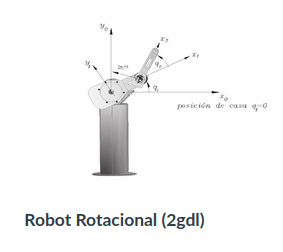

Imagen 1. Modelo

### Procedimiento

Primero se limpia la pantalla y valores, para poder declarar las variables simbólicas, es decir, no tienen un valor en específico.

clear all
close all
clc

tic

syms th1(t) th2(t)  t  %Angulos de cada articulación
syms m1 m2 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 %Masas y matrices de Inercia
syms t1 t2 %Tiempos
syms l1 l2 lc1 lc2  %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g
altura1=10

altura1 = 10

Posterioremente se hace la configuración del robot, 0 para junta rotacional, 1 para junta prismática, además de crear el vector de coordenadas articulares (Posición).

RP=[0 0];

Q= [th1, th2];
%disp('Coordenadas generalizadas');
%pretty (Q);

Sacando la derivada del vector de coordenadas articulares con la función diff, obtenemos la velocidad articular.

Qp= diff(Q, t); %diff() para derivadas con variable de referencia que no
% depende de otra: ejemplo el tiempo
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d          d        \
| -- th1(t), -- th2(t) |
\ dt         dt        /



Con la función size se declara el número de grados de libertad que tiene el robot con el vector RP previamente definido, siempre se coloca 2, ya que indica la dimensión de las columnas y se convierte a string para posteriormente declarar el nombre a las matrices.

GDL= size(RP,2);
GDL_str= num2str(GDL);

Se declaran las matrices de posición y las de rotación.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);altura1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];


%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco 
% de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de 
% referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


Ahora en un ciclo for hará el procedimiento el número de veces de grados de libertad que tenga el robot. En este for se despliega las matrices de transformación locales y las globales, con un try catch se hace la excepción si el robot sólo cuenta con un grado de libertad. La mattriz global es la multiplicación de las locales.

for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    %disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    %pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end


Ya con esto se calcula el jacobiano lineal de forma diferencial, para esta matriz se deriva parcialmente th1 y th2, respecto a los ejes. Con las derivadas acomodamos los valores y creamos la matriz del jacobiano.

%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12;
              Jv21 Jv22;
              Jv31 Jv32]);
pretty(jv_d);

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)) |
|                                                                      |
\                      0,                                 0            /



Ahora se realiza el cálculo del jacobiano lineal de forma analítica, para esto se inicializa los jacobianos analíticos (lineal y angular).

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Nuevamente se utiliza un ciclo para construir los jacobianos, con una condición haca el procedimiento para una articulación rotacional o prismática, si en RP es 0 significa que es rotacional y con 1 es prismática,  dentro de la condición hay try catch para los grados de libertad del robot.

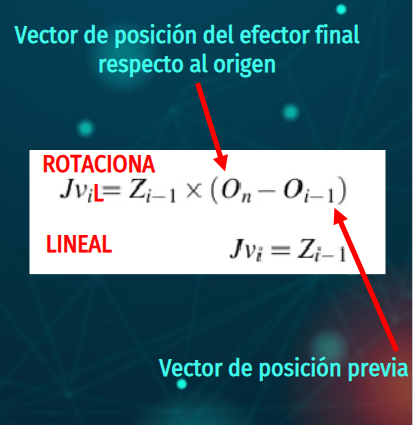

Fórmula 1.

Dependiendo del caso identificado, sea articulación rotacional o lineal, es la fórmula que se emplea.

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con
            %respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene 
            % la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)) |
|                                                                      |
\                      0,                                 0            /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /



disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   _________                               _________    \
|    d                                       d           |
| - -- th1(t) (l1 sin(th1(t)) + l2 #1) - l2 -- th2(t) #1 |
|   dt                                      dt           |
|                                                        |
|  _________                               _________     |
|   d                                       d            |
|  -- th1(t) (l1 cos(th1(t)) + l2 #2) + l2 -- th2(t) #2  |
|  dt                                      dt            |
|                                                        |
\                            0                           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/           0           \
|                       |
|           0           |
|                       |
| _________   _________ |
|  d           d        |
| -- th1(t) + -- th2(t) |
\ dt          dt        /



### **Energía cinética**

Se declara la distancia del origen del eslabón a su centro de masa con vectores de posición respecto al centro de masa.

posteriormente se crean la matrices de inercia por cada eslabón.

 P01=subs(P(:,:,1)/2, l1, lc1);
 P12=subs(P(:,:,2)/2, l2, lc2);

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

**Función de energía cinética**

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);


**Calculamos las velocidades para cada eslabón**

Esta vez necesitamos obtener la velocidad lineal y angular del primer eslabón, ya que en este robot de dos grados de libertad previamente habíamos calculado las velocidades del último eslabón. A diferencia del robot péndulo, debemos que sacar individualmente las velocidades de cada eslabón.

%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
%se resta a los grados de libertad (2-1=1) para llegar al primer eslabón
Jv_a1(:,GDL-1)=PO(:,:,GDL-1); 
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con 
            %respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene 
            % la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1)); 
%pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
% pretty(W1);



**Energía cinética para cada eslabón**

Ahora si con las velocidades podemos obtener la energía cinética individual de cada elsabón. Se ocupan los vectores previamente declarados dependiendo de que eslabón se esté calculando.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*(1/2*m1*(V1_Total)) + (1/2*W1)'*(I1*W1);
%disp('Energía Cinética en el Eslabón 1');
K1= simplify (K1);
%pretty (K1);


%Eslabón 2
V2_Total= V+cross(W,P12);
K2= (1/2*m2*(V2_Total))'*(1/2*m2*(V2_Total)) + (1/2*W)'*(I2*W);
%disp('Energía Cinética en el Eslabón 2');
K2= simplify (K2);
%pretty (K2);


Sumamos las dos energías para desplegar la total

K_Total= simplify (K1+K2);
disp('Energía Cinética del robot rotacional de dos grados de libertad');

Energía Cinética del robot rotacional de dos grados de libertad


pretty(K_Total)

               /  d           d        \
               | -- th1(t)   -- th2(t) |
Izz1 #5        | dt          dt        |
------- + Izz2 | --------- + --------- | (#3 + #2)
   2           \     2           2     /

                                                                                            /                                                                      ______  ___    \
        __ /                                                    lc2 sin(th2(t)) (#3 + #2) \ |  d                 __       ______  __            __  d          sin(th2(t)) lc2 #1 |
     m2 m2 | #3 (l1 sin(th1(t)) + l2 sin(#6)) + l2 #2 sin(#6) + ------------------------- | | -- th1(t) (sin(#4) l2 + sin(th1(t)) l1) + sin(#4) l2 -- th2(t) + ------------------ |
           \                                                                2             / \ dt                                                   dt                   2         /
   + -----------------------------------------------------------

#### **Energía potencial**

Calculamos la energía potencial para cada uno de los eslabones.

Primero se obtiene las alturas respecto a la gravedad.

Como la configuración es de dos grado de libertad, se declaran dos alturas.

A la primera se le suma la altura constante por la longitud 1 de la primera articulación que multiplica el sin(th1) del primer eslabón.

Y la segunda sólo se multiplica la longitud 2 del segundo brazo y se multiplica por sin(th2) del segundo eslabón.

De esta manera se obtiene la altura total del robot.

 h1= altura1+l1*sin(th1); %Tomo la altura paralela al eje z
 h2= l2*sin(th2); %Tomo la altura de la primer articulación

Se multiplica las alturas por las masas y la gravedad.

 U1=m1*g*h1;
 U2=m2*g*h2;

Calculamos la energía potencial total.

 U_Total= U1 + U2

$$U\_Total(t) = g\,m_{1}\,\left(l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+10\right)+g\,l_{2}\,m_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)$$

Y para obtener el Lagrangiano restamos la energia potencial a la energía cinética.

 Lagrangiano= simplify (K_Total-U_Total);
 %pretty (Lagrangiano);

Para finalmente obtener el modelo de energía sumando la energía cinética y la energía potencial.

 H= simplify (K_Total+U_Total);
 pretty (H)

                                /  d           d        \
                                | -- th1(t)   -- th2(t) |
Izz1 #5                         | dt          dt        |
------- + g m1 (#6 + 10) + Izz2 | --------- + --------- | (#3 + #2)
   2                            \     2           2     /

                                                                                /                                                                      ______  ___    \
        __ /                                        lc2 sin(th2(t)) (#3 + #2) \ |  d                 __       ______  __            __  d          sin(th2(t)) lc2 #1 |
     m2 m2 | #3 (#6 + l2 sin(#7)) + l2 #2 sin(#7) + ------------------------- | | -- th1(t) (sin(#4) l2 + sin(th1(t)) l1) + sin(#4) l2 -- th2(t) + ------------------ |
           \                                                    2             / \ dt                                                   dt                   2         /
   + ----------------------

%se recopila el tiempo que tomó ejecutar las operaciones
toc

Elapsed time is 8.062851 seconds.
